# Session 14 Exercises:

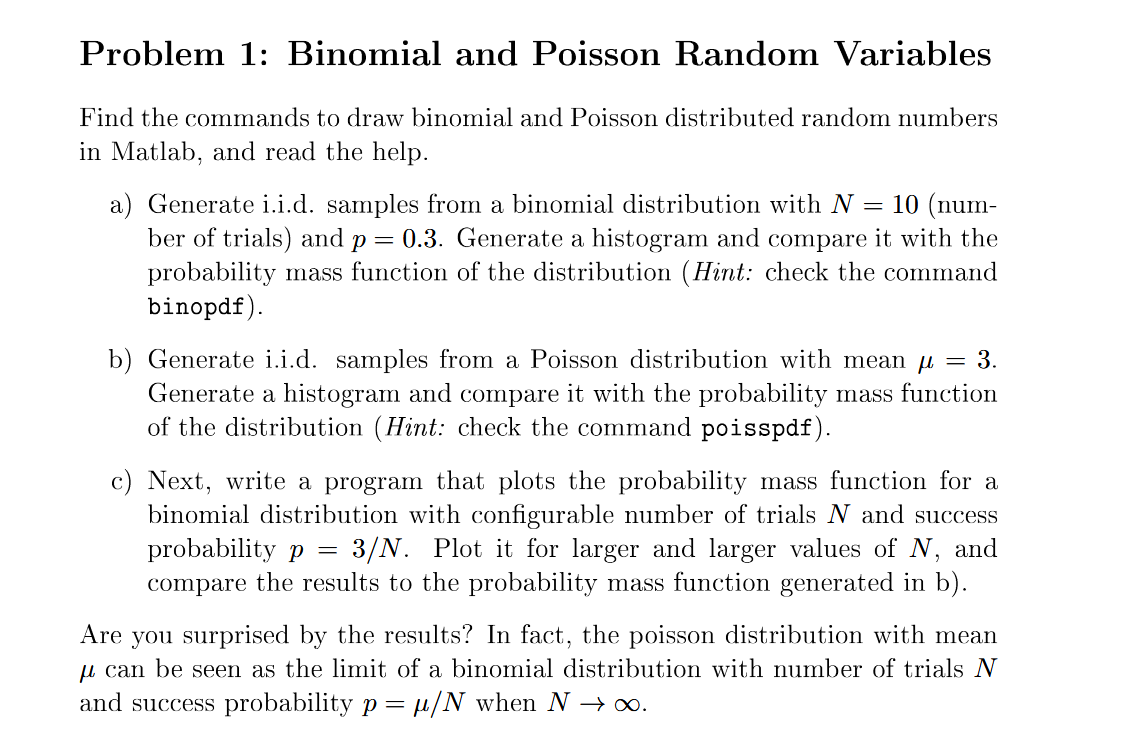

A) 

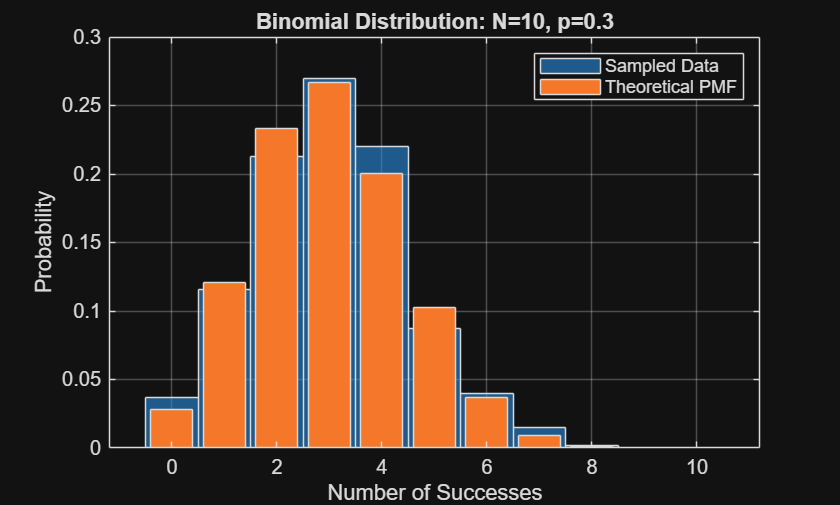

rng("default")
N = 10;          
p = 0.3;          
n_samples = 1000; 
samples = binornd(N, p, n_samples, 1);
figure;
histogram(samples, 'Normalization', 'probability');
hold on;

x = 0:N;
pmf = binopdf(x, N, p);
bar(x, pmf);

% Labels and legend
xlabel('Number of Successes');
ylabel('Probability');
title(sprintf('Binomial Distribution: N=%d, p=%.1f', N, p));
legend('Sampled', 'Theoretical PMF');
grid on;

hold off;

B)

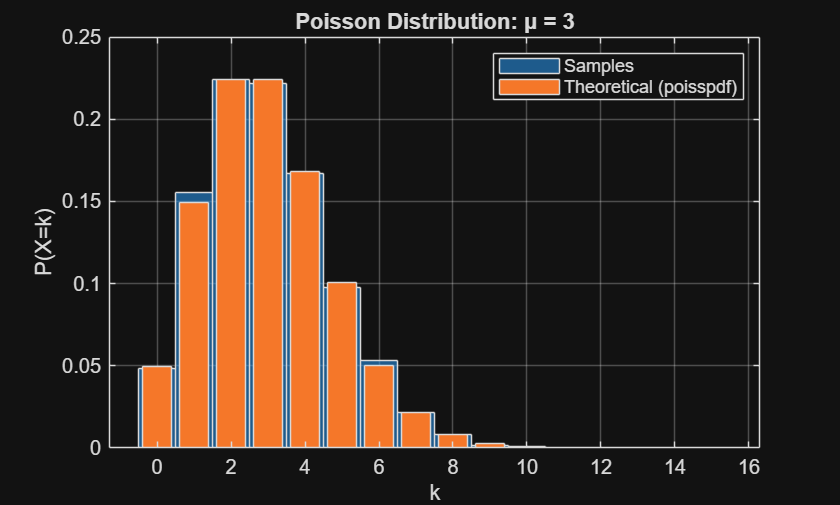

rng("default")
mu = 3;
samples = poissrnd(mu, 10000, 1);

% Plot
x = 0:15;
figure;
histogram(samples, 'BinEdges', [-0.5:max(x)+0.5], 'Normalization', 'probability');
hold on;
bar(x, poisspdf(x, mu));
xlabel('k'); ylabel('P(X=k)');
title(sprintf('Poisson Distribution: μ = %d', mu));
legend('Samples', 'Theoretical (poisspdf)');
grid on;

C) 

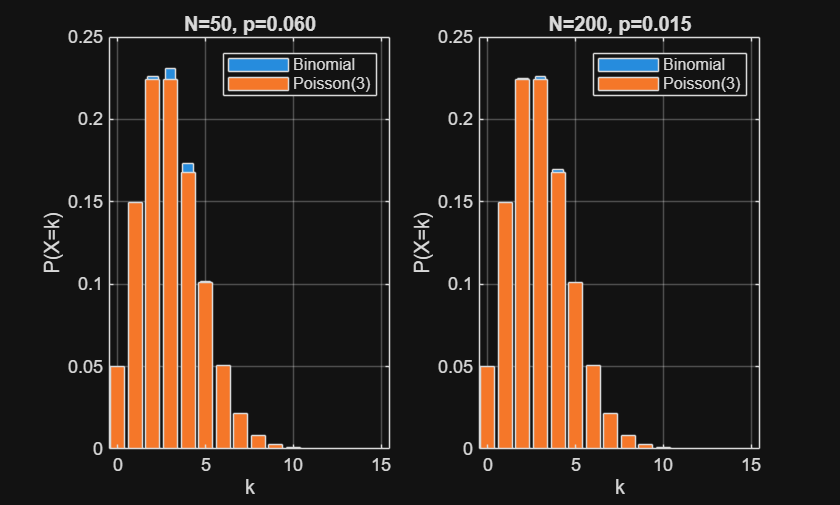

rng("default")
mu = 3;
N_vals = [50, 200];  % Two large N values
x = 0:15;

figure;
for i = 1:2
    N = N_vals(i);
    p = 3/N;
    
    subplot(1,2,i);
    bar(x, binopdf(x, N, p), 0.6);
    hold on;
    bar(x, poisspdf(x, mu));
    
    xlabel('k'); ylabel('P(X=k)');
    title(sprintf('N=%d, p=%.3f', N, p));
    legend('Binomial', 'Poisson(3)');
    grid on;
    xlim([-0.5, 15.5]);
end

Svar til sidste del af problem 1:

The hint says: when N gets very large and p gets very small (but μ = Np stays constant), the binomial distribution approaches a Poisson distribution with mean μ.

**What this means for your case:**

- Your N = 10 is relatively small, so your binomial is still clearly binomial

- But imagine if N = 100, p = 0.03 (still μ = 3)

- Or N = 1000, p = 0.003 (still μ = 3)

- As N → ∞, the binomial would look more and more like a Poisson(μ = 3)

Problem 2:

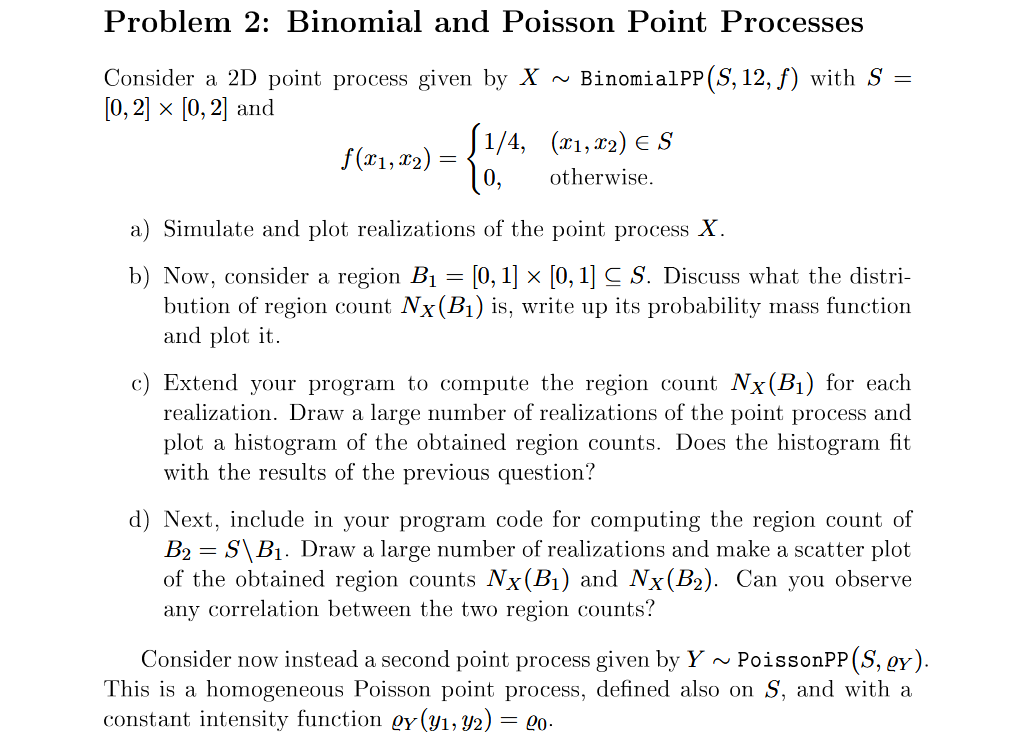

A)B)C)D)

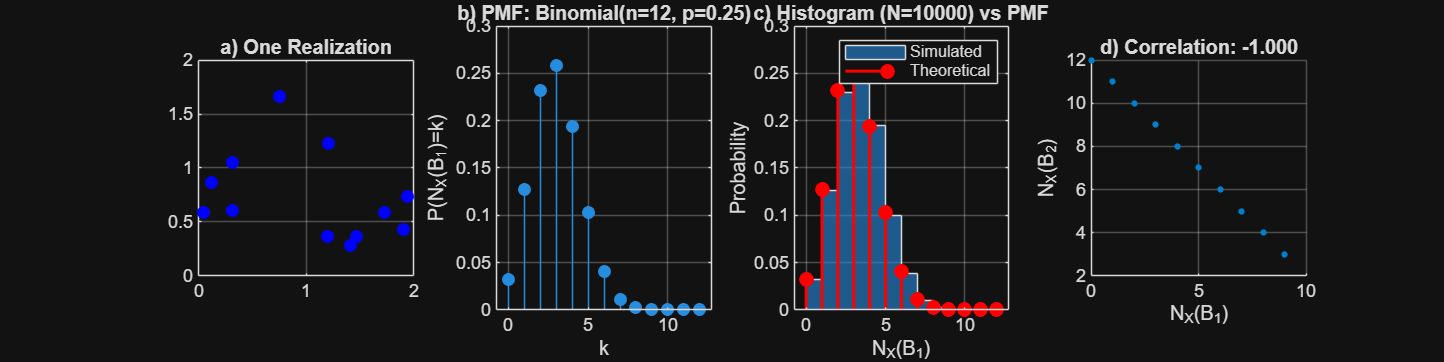

%% Setup
S = [0 2; 0 2]; B1 = [0 1; 0 1]; n = 12; p1 = 0.25; p2 = 0.75;

%% a) Simulate and plot one realization
rng(42);
X = rand(n,2)*2;
figure('Position',[100 100 1200 300]);
subplot(141); plot(X(:,1),X(:,2),'bo','MarkerFaceColor','b'); 
axis([0 2 0 2]); grid on; title('a) One Realization'); axis square;

%% b) Distribution of N_X(B1)
k = 0:n;
pmf = binopdf(k, n, p1);
subplot(142); stem(k, pmf, 'filled'); 
xlabel('k'); ylabel('P(N_X(B_1)=k)'); 
title(sprintf('b) PMF: Binomial(n=%d, p=%.2f)',n,p1)); grid on;

%% c) Histogram of N_X(B1) from many realizations
N = 10000;
counts_B1 = zeros(N,1);
for i = 1:N
    X = rand(n,2)*2;
    counts_B1(i) = sum(X(:,1)<=1 & X(:,2)<=1);
end
subplot(143); histogram(counts_B1, 'Normalization','probability', 'BinWidth',1);
hold on; stem(k, pmf, 'r', 'filled', 'LineWidth',1.5);
xlabel('N_X(B_1)'); ylabel('Probability'); 
title(sprintf('c) Histogram (N=%d) vs PMF',N)); 
legend('Simulated','Theoretical'); grid on;

%% d) Scatter plot of N_X(B1) vs N_X(B2)
counts_B2 = n - counts_B1;
subplot(144); scatter(counts_B1, counts_B2, 10, 'filled', 'MarkerFaceColor',[0 0.5 0.8]);
xlabel('N_X(B_1)'); ylabel('N_X(B_2)'); 
title(sprintf('d) Correlation: %.3f',corr(counts_B1,counts_B2))); 
grid on; axis square;

Short answers:

**Key Points:**

- **a)** 12 uniform random points in [0,2]×[0,2]

- **b)** Since f is uniform over S, N_X(B₁) ~ **Binomial(12, 1/4)** because B₁ has area 1 and S has area 4, so p = Area(B₁)/Area(S) = 1/4

- **c)** The histogram matches the theoretical PMF very well

- **d)** **Strong negative correlation** (≈ -1) is observed because N_X(B₁) + N_X(B₂) = 12 (constant), creating a perfect linear negative relationship

The code generates all four plots in one figure window showing the progression from single realization to statistical validation.

e)f)g)h)i)

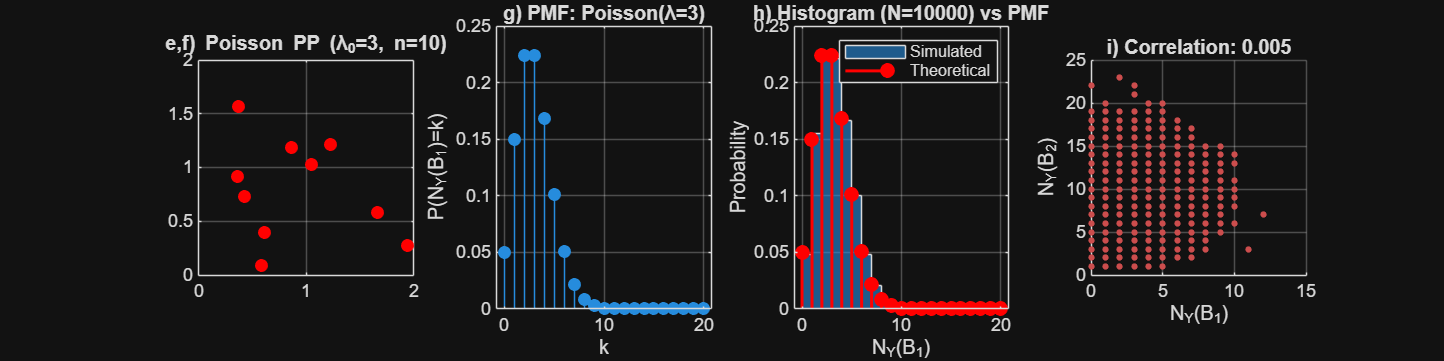

%% Setup
B1 = [0 1; 0 1]; 
lambda0 = 3; % f) E[N_Y(S)] = lambda0 * 4 = 12, so lambda0=3

%% e) & f) Simulate and plot one realization of Poisson PP
rng(42);
N_points = poissrnd(lambda0*4); % Total points in [0,2]x[0,2]
Y = rand(N_points,2)*2;
figure('Position',[100 100 1200 300]);
subplot(141); plot(Y(:,1),Y(:,2),'ro','MarkerFaceColor','r'); 
axis([0 2 0 2]); grid on; 
title(sprintf('e,f) Poisson PP (λ_0=%g, n=%d)',lambda0,N_points)); axis square;

%% g) Distribution of N_Y(B1)
lambda_B1 = lambda0*1; % Intensity * Area(B1) = 3*1 = 3
k = 0:20;
pmf = poisspdf(k, lambda_B1);
subplot(142); stem(k, pmf, 'filled'); 
xlabel('k'); ylabel('P(N_Y(B_1)=k)'); 
title(sprintf('g) PMF: Poisson(λ=%g)',lambda_B1)); grid on;

%% h) Histogram of N_Y(B1) from many realizations
N_sim = 10000;
counts_B1 = zeros(N_sim,1);
for i = 1:N_sim
    N_points = poissrnd(lambda0*4);
    Y = rand(N_points,2)*2;
    counts_B1(i) = sum(Y(:,1)<=1 & Y(:,2)<=1);
end
subplot(143); histogram(counts_B1, 'Normalization','probability', 'BinWidth',1);
hold on; stem(k, pmf, 'r', 'filled', 'LineWidth',1.5);
xlabel('N_Y(B_1)'); ylabel('Probability'); 
title(sprintf('h) Histogram (N=%d) vs PMF',N_sim)); 
legend('Simulated','Theoretical'); grid on;

%% i) Scatter plot of N_Y(B1) vs N_Y(B2)
counts_B2 = zeros(N_sim,1);
for i = 1:N_sim
    N_points = poissrnd(lambda0*4);
    Y = rand(N_points,2)*2;
    counts_B2(i) = sum(Y(:,1)>1 | Y(:,2)>1);
end
subplot(144); scatter(counts_B1, counts_B2, 10, 'filled', 'MarkerFaceColor',[0.8 0.3 0.3]);
xlabel('N_Y(B_1)'); ylabel('N_Y(B_2)'); 
title(sprintf('i) Correlation: %.3f',corr(counts_B1,counts_B2))); 
grid on; axis square;

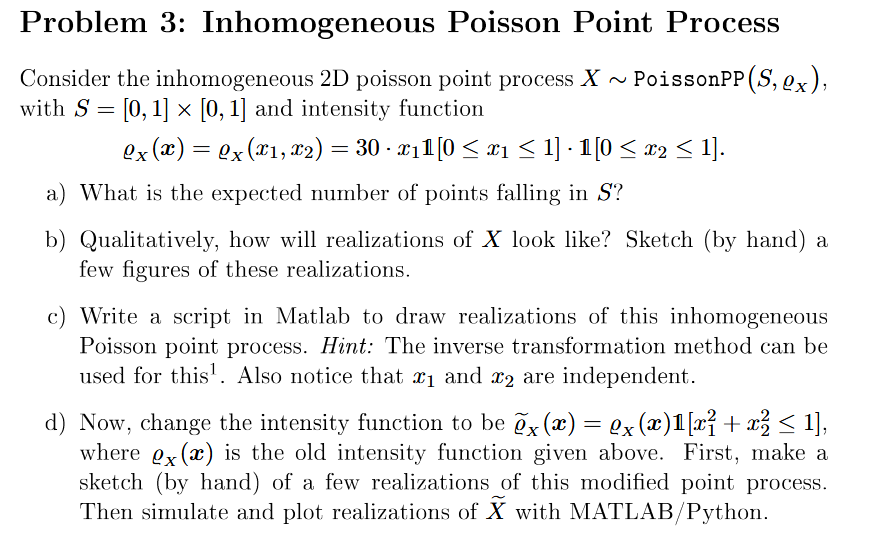

a) Lavet på papir:

## b) and c) since it generates the realization and plots it

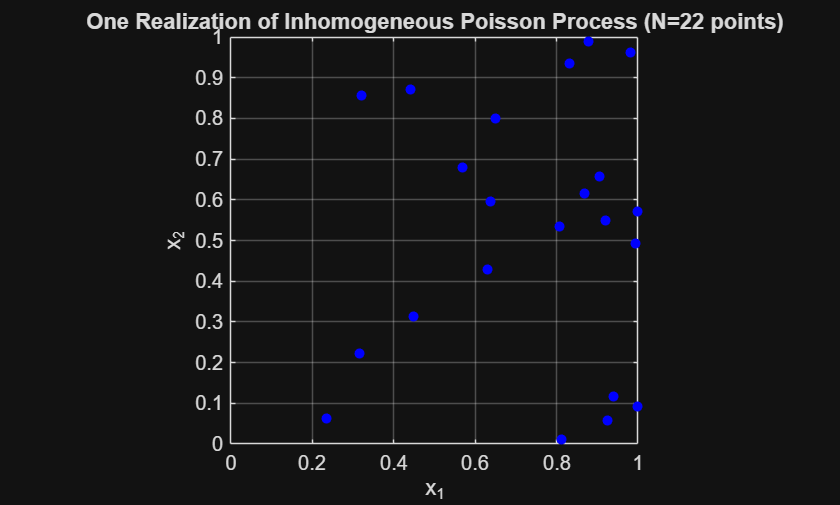

% Minimal script to visualize the inhomogeneous Poisson process
% Intensity function: rho(x1, x2) = 30 * x1

% Step 1: Expected number of points
lambda = 15;  % We calculated this as the integral of 30*x1 over [0,1]x[0,1]

% Step 2: Generate the number of points from Poisson distribution
N = poissrnd(lambda);

% Step 3: Generate coordinates for each point
% x1 follows the distribution with density proportional to x1
% Using inverse CDF: if U ~ Uniform(0,1), then x1 = sqrt(U)
u = rand(N, 1);  % Generate N uniform random numbers
x1 = sqrt(u);    % Transform using inverse CDF

% x2 is uniformly distributed since intensity doesn't depend on x2
x2 = rand(N, 1);

% Step 4: Visualize the realization
figure;
plot(x1, x2, 'b.', 'MarkerSize', 15);
xlabel('x_1');
ylabel('x_2');
title(sprintf('One Realization of Inhomogeneous Poisson Process (N=%d points)', N));
xlim([0 1]);
ylim([0 1]);
grid on;
axis square;  % Make the plot square to match the unit square region

% Calculate the condition for the inequality
condition = x1.^2 + x2.^2 <= 1;

% Extract the points that satisfy the condition
x1_safe = x1(condition);
x2_safe = x2(condition);

## d) With new constraints

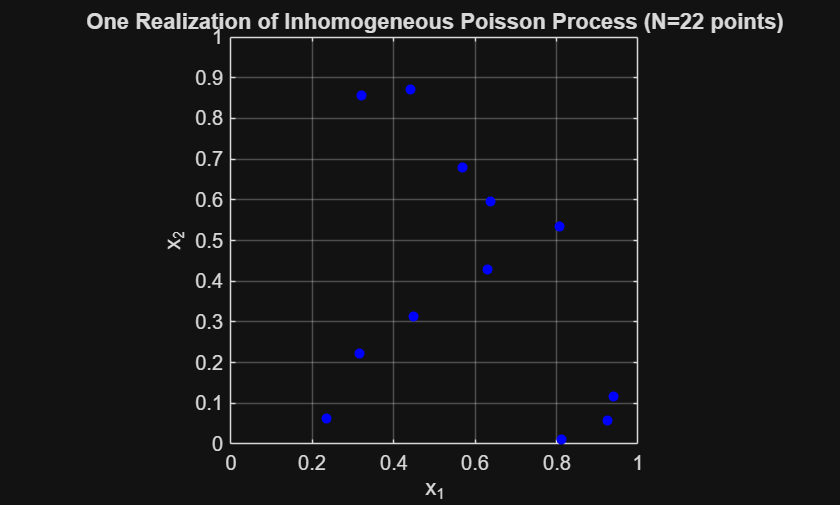

figure;
plot(x1_safe, x2_safe, 'b.', 'MarkerSize', 15);
xlabel('x_1');
ylabel('x_2');
title(sprintf('One Realization of Inhomogeneous Poisson Process (N=%d points)', N));
xlim([0 1]);
ylim([0 1]);
grid on;
axis square;

## Problem 4

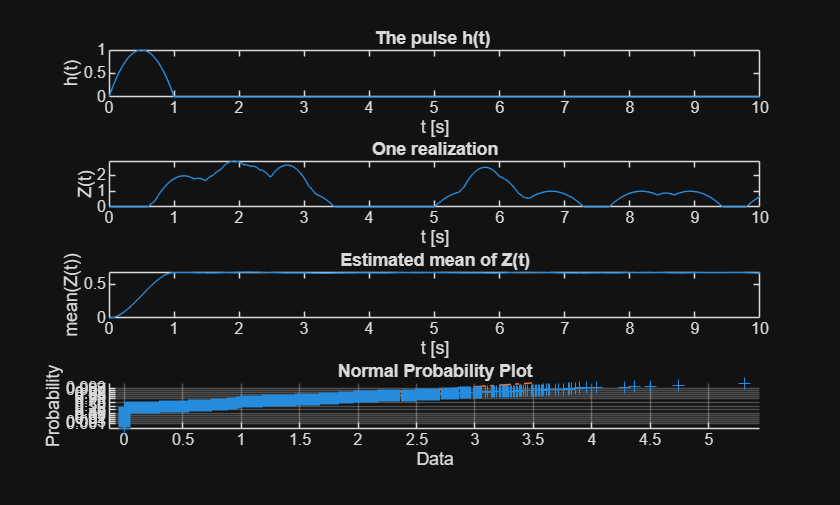

% This script is for Stochastic processes Lecture 14,
% 
% Mathias Jørgensen, AAU, Oct. 2025

% Simulation Setup
% Intensity function. Does not change the pulses,
% but changes the number of pulses.
% So large rho gives more pulses
rho0 = 1; 
tMin = 0;
tMax = 10;

nMonteCarlo = 10000;
nTimeSample = 1000;
time = linspace(tMin,tMax,nTimeSample);
Zsample = zeros(nMonteCarlo,nTimeSample);

% Pulse function
h =  @(t) (t>=0).*(t<=1).*(-4.*t.^2+4.*t); % Anonymous function 

% Run Monte Carlo simulation
% The Monte Carlo simulation generates a number of random realizations,
% where one realization is the sum of pulse functions, at random time intervals
% The number of pulses in the realization is generated from poisson.
for iMonteCarlo = 1:nMonteCarlo
% Draw homogeneous poisson Process
N  = random('Poisson',(tMax-tMin)*rho0); 
tau = rand(N,1)*tMax;

% Make annonymoys function for shot noise:
Z = @(t) 0; 
for index = 1:N
Z = @(t) Z(t) + h(t-tau(index));
end
% Evaluate and store function values into matrix
Zsample(iMonteCarlo,:) = Z(time);
end

% Plotting
% We see a single deterministic pulse h(t):
subplot(411)
plot(time,h(time))
xlabel('t [s]')
ylabel('h(t)')
title('The pulse h(t) ')

% One Monte Carlo realization, that sums the pulse functions
subplot(412)
plot(time,Z(time))
xlabel('t [s]')
ylabel('Z(t)')
title('One realization')

% For a stationary process we expect the mean of Z(t) to be constant over time, here it equals 2/3.
% 2x rho gives 2x mean.
subplot(413)
plot(time,mean(Zsample))
xlabel('t [s]')
ylabel('mean(Z(t))')
title('Estimated mean of Z(t)')

% Shows all the values for t=10(t_max) of Z(t). The realizations are mostly
% 0. The probability is cumulatative.
% A higher rho, gives larger values, therefore, the norm plot has higher
% data values, and less prominent probability of 0.
subplot(414)
normplot(Zsample(:,end))

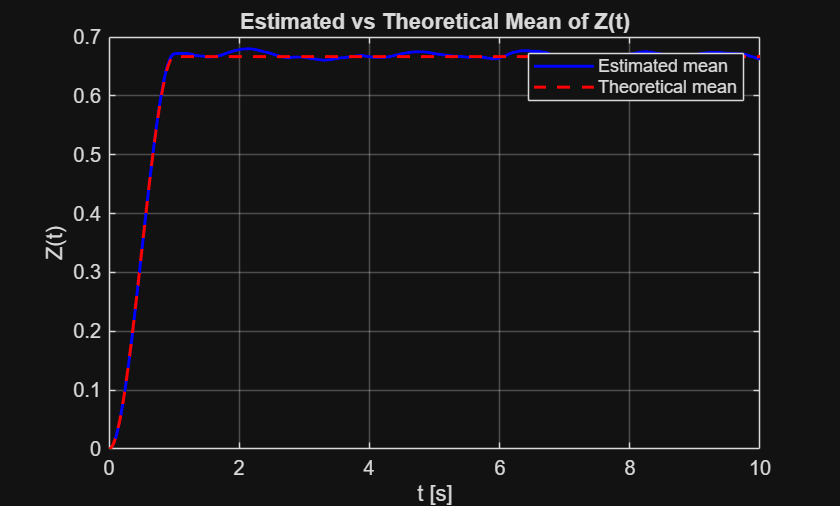


% Exercise d

% For each time t, integrate h(tau) over shifted interval
E_Zt = zeros(size(time));
for k = 1:length(time)
    t = time(k);
    tauLimits = [tMin, tMax];
    % Integrate h(t - tau) over tau from tMin to tMax
    E_Zt(k) = rho0 * integral(@(tau) h(t - tau), tauLimits(1), tauLimits(2));
end

% Plot
figure;
plot(time, mean(Zsample), 'b', 'LineWidth', 1.5)
hold on
plot(time, E_Zt, 'r--', 'LineWidth', 1.5)
xlabel('t [s]')
ylabel('Z(t)')
legend('Estimated mean', 'Theoretical mean')
title('Estimated vs Theoretical Mean of Z(t)')
grid on

I'll walk you through this shot noise simulation code in detail. Shot noise is a fundamental concept in stochastic systems, modeling random pulses arriving at random times.**Mathematical Foundation**

Shot noise is modeled as: $$Z(t) = \sum_{i=1}^{N(t)} h(t - \tau_i)$$

Where:

- $N(t)$ is a Poisson point process (random arrival times)

- $\tau_i$ are the arrival times

- $h(t)$ is the impulse response (pulse shape)

## Code Breakdown

1. Simulation Setup

`rho0 = 1;              % Intensity (rate) of Poisson process: λ = 1 event/second`

`tMin = 0;              % Start time`

`tMax = 10;             % End time (10 second observation window)`

`nMonteCarlo = 100;     % Number of independent realizations`

`nTimeSample = 1000;    % Time discretization points`

`time = linspace(tMin,tMax,nTimeSample);  % Time vector`

`Zsample = zeros(nMonteCarlo,nTimeSample); % Storage for all realizations`

**2. Impulse Response Function**

`h = @(t) (t>=0).*(t<=1).*(-4.*t.^2+4.*t);`

This defines the pulse shape - a **parabolic pulse** that:

- Is zero for $t < 0$ (causal)

- Is zero for $t > 1$ (finite duration)

- For $0 \leq t \leq 1$: $h(t) = -4t^2 + 4t = 4t(1-t)$

- Peaks at $t = 0.5$ with maximum value $h(0.5) = 1$

- Returns smoothly to zero at $t = 1$

**3. Monte Carlo Simulation Loop**

For each realization:

**Step A: Generate Random Arrivals**

`N = random('Poisson',(tMax-tMin)*rho0);`

- Draws the **number of events** from Poisson($\lambda T$) distribution

- With $\rho_0 = 1$ and $T = 10$, expect about $N \approx 10$ events

- This number varies randomly each realization

**Step B: Generate Arrival Times**

`tau = rand(N,1)*tMax;`

- Uniformly distributes $N$ arrival times in $[0, 10]$

- This is equivalent to sampling a homogeneous Poisson point process

**Step C: Build Shot Noise Process**

`Z = @(t) 0;`

`for index = 1:N`

`    Z = @(t) Z(t) + h(t-tau(index));`

`end`

This is clever but **computationally inefficient**:

- Starts with $Z(t) = 0$

- For each arrival at $\tau_i$, adds the pulse $h(t - \tau_i)$

- Creates nested anonymous functions (each call evaluates all previous pulses)

- Result: $Z(t) = \sum_{i=1}^{N} h(t - \tau_i)$

**Step D: Sample and Store**

`Zsample(iMonteCarlo,:) = Z(time);`

- Evaluates $Z(t)$ at 1000 time points

- Stores in matrix (each row = one realization)

**4. Visualization**

**Subplot 1:** Shows the pulse shape $h(t)$

- Single parabolic pulse from 0 to 1 second

**Subplot 2:** Shows one realization $Z(t)$

- Superposition of randomly placed pulses

- Each pulse appears at random $\tau_i$

**Subplot 3:** Estimated mean

`plot(time,mean(Zsample))`

- Averages across 100 realizations

- Theoretical mean: $E[Z(t)] = \rho_0 \int_{-\infty}^{t} h(t-s)ds = \rho_0 \int_{0}^{1} h(u)du$

- For this $h(t)$: $\int_0^1 4t(1-t)dt = \frac{2}{3}$

- So $E[Z(t)] = \frac{2}{3}$ (for $t \geq 1$)

**Subplot 4:** Normal probability plot    

`normplot(Zsample(:,end))`

- Tests if $Z(t=10)$ is approximately Gaussian

- By the **Campbell's theorem** and Central Limit Theorem, shot noise with many pulses approaches Gaussian distribution

## Key Insights

- **Randomness sources:** Both the *number* and *timing* of pulses are random

- **Transient behavior:** For $t < 1$, the mean ramps up as pulses begin to accumulate

- **Steady state:** For $t \geq 1$, process reaches statistical equilibrium

- **Gaussian approximation:** With high arrival rate, shot noise ≈ Gaussian (validated by normplot)

- **Inefficiency:** The nested anonymous function approach is slow; vectorized computation would be much faster

This type of model applies to electron emissions, neural spike trains, photon arrivals, and many physical phenomena!